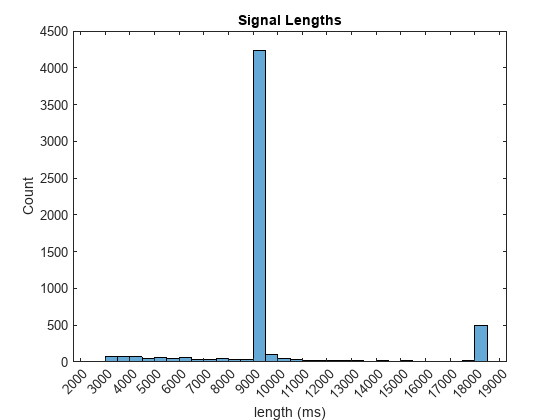

if ~isfile('PhysionetData.mat')
    ReadPhysionetData         
end
load PhysionetData

% graph to visualize the length of the data
L = cellfun(@length,Signals);
h = histogram(L);
xticks(0:1000:20000);
xticklabels(0:1000:20000);
title('Signal Lengths')
xlabel('length (ms)')
ylabel('Count')


% most data has length of 9000 ms

% train model using only the ECGs with length of 9000 ms, delete the others 
[signals_9000, labels_9000] = segmentSignals(Signals, Labels);
 
fs = 300; % frequency of ECGs (Hz)

% creates array excluding signals different than 9000ms
arrX = signals_9000(labels_9000 =='A'); 
arrY = labels_9000(labels_9000 =='A');

normX = signals_9000(labels_9000 =='N');
normY = labels_9000(labels_9000 =='N');
 
% used number of arrythmic signals (limits number of signals)
[trainIndexArr,~,testIndexArr] = dividerand(718,0.85,0.0,0.15); % divides signals into training and testing groups (85% training, 15% testing)
[trainIndNorm,~,testIndNorm] = dividerand(718,0.85,0.0,0.15);

XTrainArr = arrX(trainIndexArr); % creates arrythmic (uses the signals) group to TRAIN program
YTrainArr = arrY(trainIndexArr); % creates arrythmic (uses the labels) group to TRAIN program

XTrainNorm = normX(trainIndNorm); % creates normal (uses the signals) group to TRAIN program
YTrainNorm = normY(trainIndNorm); % creates normal (uses the labels) group to TRAIN program

XTestArr = arrX(testIndexArr); % creates arrythmic (uses the signals) group to TEST program
YTestArr = arrY(testIndexArr); % creates arrythmic (uses the labels) group to TEST program

XTestNorm = normX(testIndNorm); % creates normal (uses the signals) group to TEST program
YTestNorm = normY(testIndNorm); % creates normal (uses the labels) group to TEST program

% find size for training and testing groups
signals_85percent = floor(718 * 0.85);
signals_15percent = floor(718 * 0.15);

XTrain = [repmat(XTrainArr(1:signals_85percent),1,1); XTrainNorm(1:signals_85percent)]; % creates group of ALL training signals
YTrain = [repmat(YTrainArr(1:signals_85percent),1,1); YTrainNorm(1:signals_85percent)]; % creates group of ALL training labels

XTest = [repmat(XTestArr(1:signals_15percent),1,1); XTestNorm(1:signals_15percent)]; % creates group of ALL testing signals
YTest = [repmat(YTestArr(1:signals_15percent),1,1); YTestNorm(1:signals_15percent);]; % creates group of ALL training labels

% increase accurcy through the following steps

% uniform output, false ensures that the output can be of varying sizes (reducing probabilty to get an error)

%  estimates instantaneous frequency of a signal (arr_signal), sampled at a rate fs applying function to each cell array (cellfun)
inst_freq_Train = cellfun(@(x)instfreq(x,fs)',XTrain,'UniformOutput',false); % vector representing the instantaneous frequency of ECG signal in `XTrain`.
inst_freq_Test = cellfun(@(x)instfreq(x,fs)',XTest,'UniformOutput',false); % vector representing the instantaneous frequency of ECG signal in `XTrain`.

% measure of spectral power distribution
% spectral entropy measures how spiky or flat the spectrum of a signal is. A spiky spectrum = low spectral entropy
pentropy_Train = cellfun(@(x)pentropy(x,fs)',XTrain,'UniformOutput',false); % calculates the pentropy values for each ECG signal in the XTrain cell arra
pentropy_Test = cellfun(@(x)pentropy(x,fs)',XTest,'UniformOutput',false); % calculates the pentropy values for each ECG signal in the XTest cell arra

% add the new steps to train and differentiate the training signals (for higher accuracy)
% matrix formed by vertically concatenating the instfreq and pentropy values for a specific ECG signals - new sets have 2 dimensions
XTrain_new = cellfun(@(x,y)[x;y],inst_freq_Train,pentropy_Train,'UniformOutput',false);
XTest_new = cellfun(@(x,y)[x;y],inst_freq_Test,pentropy_Test,'UniformOutput',false);

Xtrain_mat = [XTrain_new{:}]; % creates a matrix where the columns represent the dimensions (inst_freq and pentropy), and each row corresponds to a data point (an ECG signal).

% create parameters to include/exclude normal and arrythmic signals based on mean and standard deviation
avg = mean(Xtrain_mat,2); % calculates mean
SD = std(Xtrain_mat,[],2); % calculates standard deviation

% applies mean and standard deviation to all training set
XTrainSD = XTrain_new; % copy of original training set
XTrainSD = cellfun(@(x)(x-avg)./SD,XTrainSD,'UniformOutput',false); % subtracts the average and divides by the standard deviation element-wise for training set

XTestSD = XTest_new; % copy of original testing set
XTestSD = cellfun(@(x)(x-avg)./SD,XTestSD,'UniformOutput',false);  % subtracts the average and divides by the standard deviation element-wise for testing set

% program training setup - based on online values 'standard'
layers = [ ...
    sequenceInputLayer(2)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

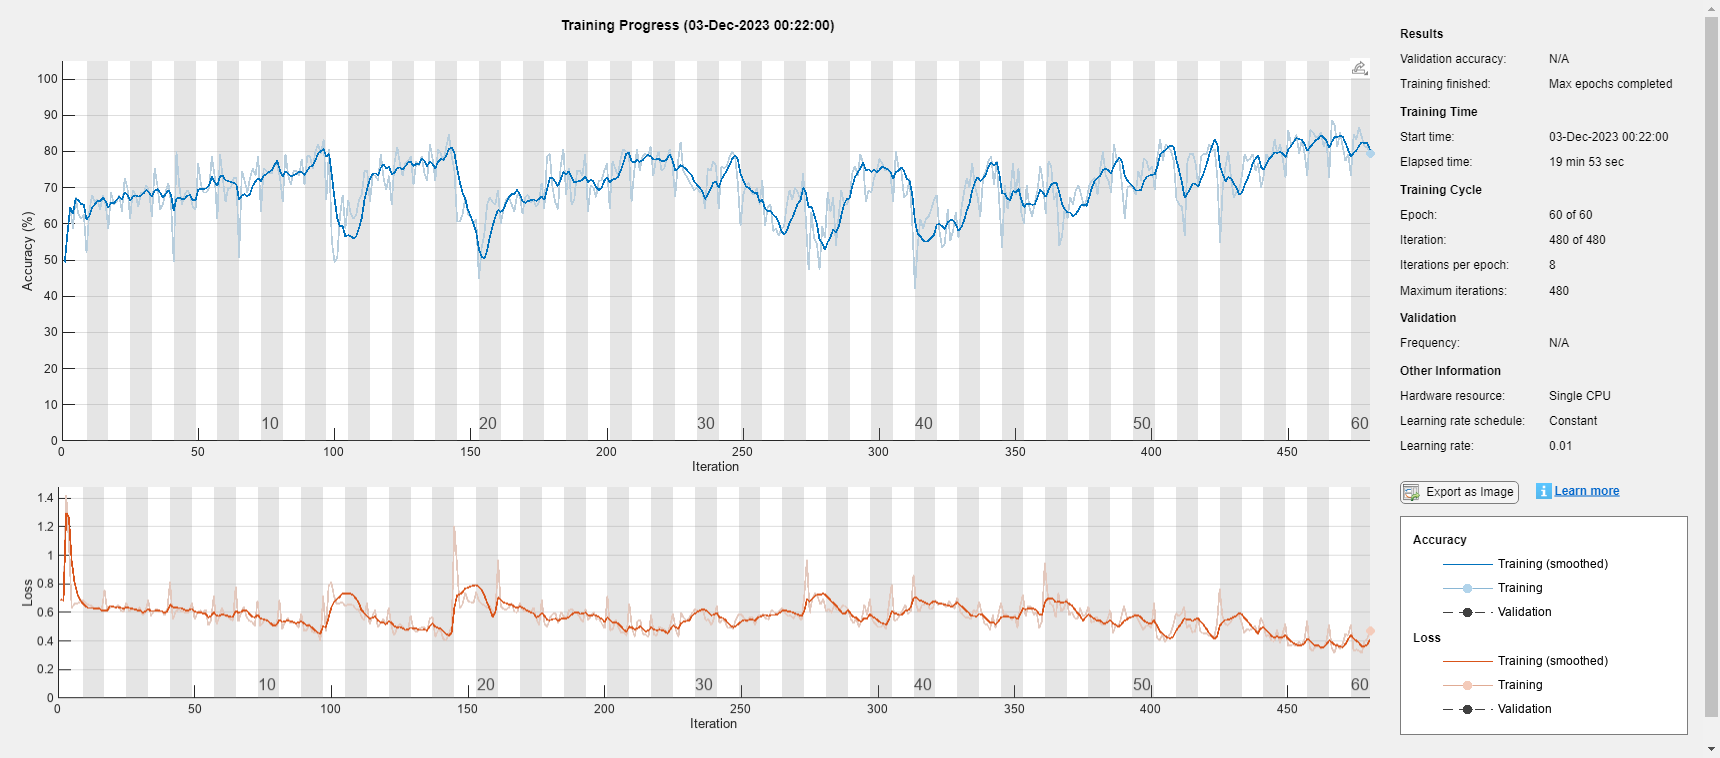


options = trainingOptions('adam', ...
    'MaxEpochs',60, ... % increased to 60 iterations to increase accuracy
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

% initialize training network
ecg_net = trainNetwork(XTrainSD,YTrain,layers,options);


save('trained_network_ECG_60epoch_700files_model2.mat', 'ecg_net');